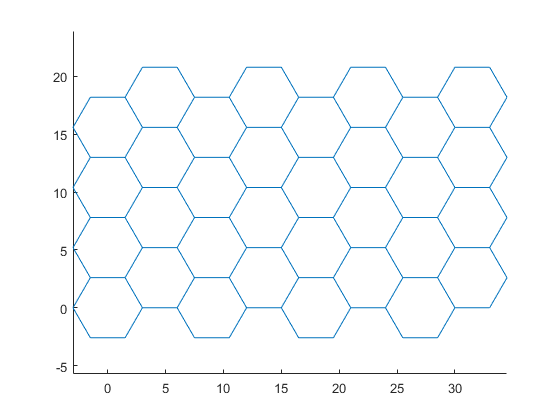


    clf;
    r = 3; %distance btwn hexes
    l=4; %len and height of display
    b=4;
    
    C0=rand(l,b); %random color
    C1=rand(l,b);
    xhex=[-r/2 -r -r/2 r/2 r r/2 -r/2]; % x-coordinates of the vertices
    yhex=[r*sqrt(3)/2 0 -r*sqrt(3)/2 -r*sqrt(3)/2 0 r*sqrt(3)/2 r*sqrt(3)/2]; % y-coordinates of the vertices
    
    %Color Arrays
    for i=1:l
        for j=1:b
            C0(i,l)=i+j/10;
            C1(i,l)=i+0.5 + j/10 +0.1;
        end
    end
    
    clf;
    for i=1:l
        for j=1:b
            line(xhex+(i-1)*3*r,yhex+(j-1)*r*sqrt(3))
            line(xhex+3/2*r+(i-1)*3*r,yhex+r*sqrt(3)/2+(j-1)*r*sqrt(3))
            
            hold on
            
        end
    end
    axis equal

%%Get Positions
HexHeight = r*sqrt(3)/2;
HexPos = [];
    for i=1:b
        for j=1:l
            if(mod(j,2)==1)
            XhexPos(i,j) = i*3*r
            else
                XhexPos(i,j) = i*3*r+3/2*r;
            end
            
            %patch(xhex+(i-1)*3*r,yhex+(j-1)*r*sqrt(3),C0(i,l))
            %patch(xhex+3/2*r+(i-1)*3*r,yhex+r*sqrt(3)/2+(j-1)*r*sqrt(3),C1(i,l))
            hold on
        end
    end

XhexPos = 9

XhexPos =     9.0000   13.5000    9.0000


XhexPos =     9.0000   13.5000    9.0000   13.5000
   18.0000         0         0         0


XhexPos =     9.0000   13.5000    9.0000   13.5000
   18.0000   22.5000   18.0000         0


XhexPos =     9.0000   13.5000    9.0000   13.5000
   18.0000   22.5000   18.0000   22.5000
   27.0000         0         0         0


XhexPos =     9.0000   13.5000    9.0000   13.5000
   18.0000   22.5000   18.0000   22.5000
   27.0000   31.5000   27.0000         0


XhexPos =     9.0000   13.5000    9.0000   13.5000
   18.0000   22.5000   18.0000   22.5000
   27.0000   31.5000   27.0000   31.5000
   36.0000         0         0         0


XhexPos =     9.0000   13.5000    9.0000   13.5000
   18.0000   22.5000   18.0000   22.5000
   27.0000   31.5000   27.0000   31.5000
   36.0000   40.5000   36.0000         0


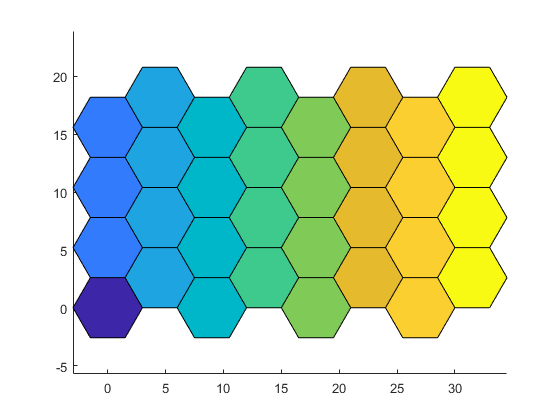



hold on
patch(xhex,yhex,0.2)

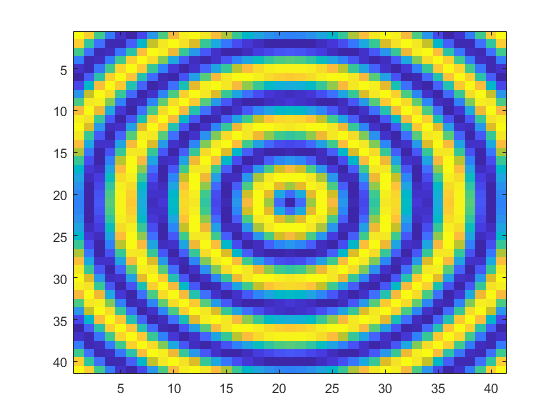

    clf;
    
    
    %Cartesian Sampling
x1 = -10:0.5:10;
y1 = -10:0.5:10;

[x y]= meshgrid(x1, y1);
f = cos(cos(sqrt(x.^2+y.^2)));
figure;
imagesc(f);

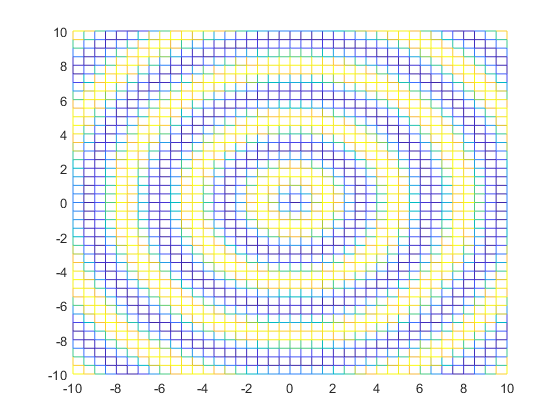

figure
mesh(x,y, f);
view([0 90.000])

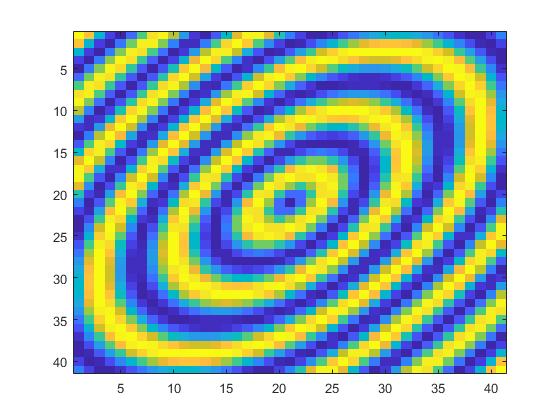


%the sampling lattice is
%[x y]’ = |sqrt(3)/2 0| |i|
% |1/2 1| |j|
%hexagonal smapling
i = x;
j = y;
x = i*sqrt(3)/2 +0;
y = i*1/2 + j;
%x = i*sqrt(3)/2 +0;
f = cos(cos(sqrt(x.^2+y.^2)));
figure;
imagesc(f);

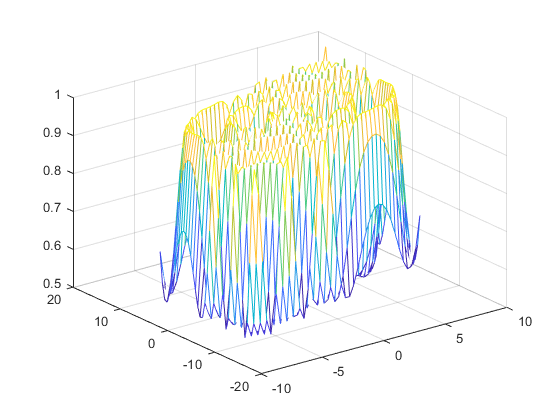

figure
mesh(x,y, f);

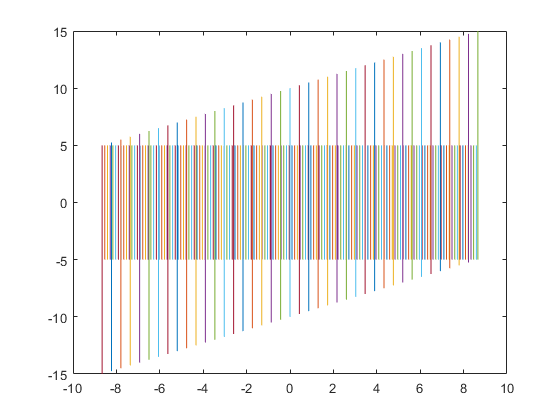


%TRYING TO RECOVER ORIGNAL SAMPLING
%i = -20:0.1/1.5:20;
minx = min(x(:));
maxx = max(x(:));
miny = min(y(:));
maxy = max(y(:));

miny = y(1,end);
maxy = y(end,1);

i = minx:0.5/4:maxx;
j = miny:0.5/4:maxy;
%j = -20:0.1:20;

[x2d y2d]= meshgrid(i, j);
figure;
plot(x2d,y2d);hold on; plot(x,y)


v = zeros(size(x2d));
for i=1:size(x2d,1)
i
for j=1:size(x2d,2)
%b = boxSplineD2(x-x2d(i,j),y- y2d(i,j));
v(i,j)= sum(sum(b.*f));

end
end

i = 1

i = 2

i = 3

i = 4

i = 5

i = 6

i = 7

i = 8

i = 9

i = 10

i = 11

i = 12

i = 13

i = 14

i = 15

i = 16

i = 17

i = 18

i = 19

i = 20

i = 21

i = 22

i = 23

i = 24

i = 25

i = 26

i = 27

i = 28

i = 29

i = 30

i = 31

i = 32

i = 33

i = 34

i = 35

i = 36

i = 37

i = 38

i = 39

i = 40

i = 41

i = 42

i = 43

i = 44

i = 45

i = 46

i = 47

i = 48

i = 49

i = 50

i = 51

i = 52

i = 53

i = 54

i = 55

i = 56

i = 57

i = 58

i = 59

i = 60

i = 61

i = 62

i = 63

i = 64

i = 65

i = 66

i = 67

i = 68

i = 69

i = 70

i = 71

i = 72

i = 73

i = 74

i = 75

i = 76

i = 77

i = 78

i = 79

i = 80

i = 81

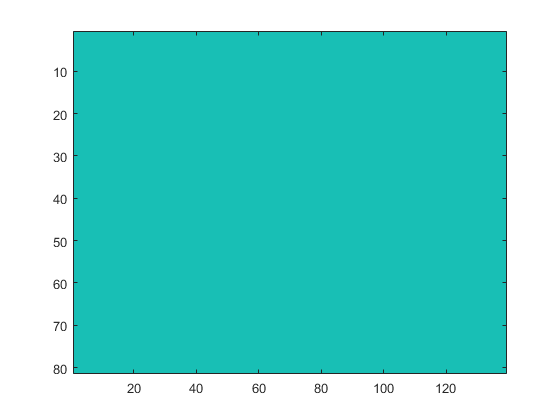


figure;
imagesc(v);

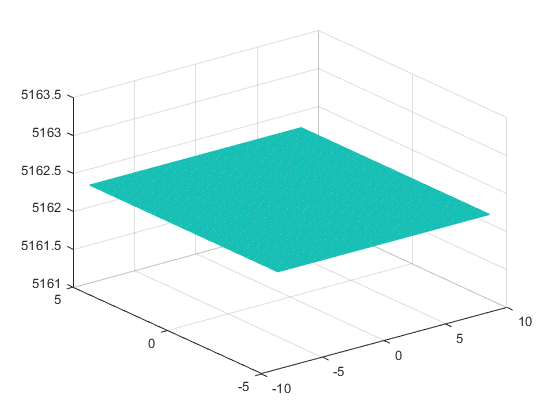

figure
mesh(x2d,y2d, v);